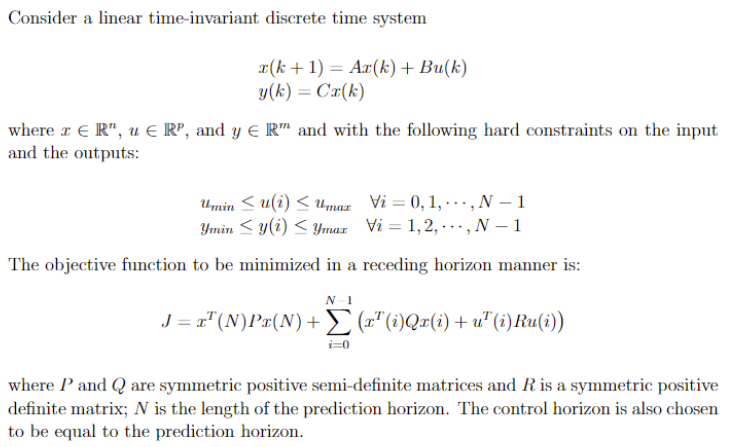

Below is a sample code to simulate a linear MPC.

**get_QP** function which forms the QP matrices 

**do_MPC** function calculates the receeding horizon controller for the given system.

## System setup

clc; clear;

% define a discrete time linear system
% x(k+1) =A_d*x(k) + B_d*u(k)
% y(k) = C_d*x(k)

A_d = [1 0 0; 1 2 0; 1 2 3];
B_d = [1 1; 1 1; 1 1];
C_d = eye(3,3);

system.A = A_d;
system.B = B_d;
system.C = C_d;
system.n = size(A_d,2);
system.p = size(B_d,2);
system.m = size(C_d,2);

## MPC setup

mpc.dT = 0.1; % Discretization and simulation timestep
mpc.N = 10; % prediction horizon

% define MPC cost
% stage cost (running cost): x'*Q*X + u'*R*u 
% terminal cost: x'*P'x
mpc.Q = eye(3,3);
mpc.R = eye(2,2);
mpc.P = eye(3,3);

% input bounds
bounds.u_min = [];%[-3; -5]; 
bounds.u_max = [];%[5; 5];

% output bounds
bounds.y_min = [-5;-5;-5];
bounds.y_max = [5;5;5];

## **Get QP Matrices**

% collect info needed for QP
[F, G, A_ineq, B_ineq] = get_QP(system,mpc,bounds);

## **Simulate MPC with quadprog**

% initialize
x0 = [1;1;1];  
t = 0;

% unpack info
p = system.p;
dT = mpc.dT;

% data logging
X_log = x0; T_log = t;
U_log = [];

% simulation loop
max_iter = 10;
x = x0;
for i = 1:max_iter

    % get MPC controller
    U = do_MPC(G,x'*F',A_ineq,B_ineq,x);
    u = U(1:p);
    
    % simulate discrete time system
    x = A_d*x + B_d*u;

    % log data
    T_log = [T_log, t];
    X_log = [X_log, x];
    U_log = [U_log, u]; 
    
    % update sim time
    t = i*dT;
end 

## Plots

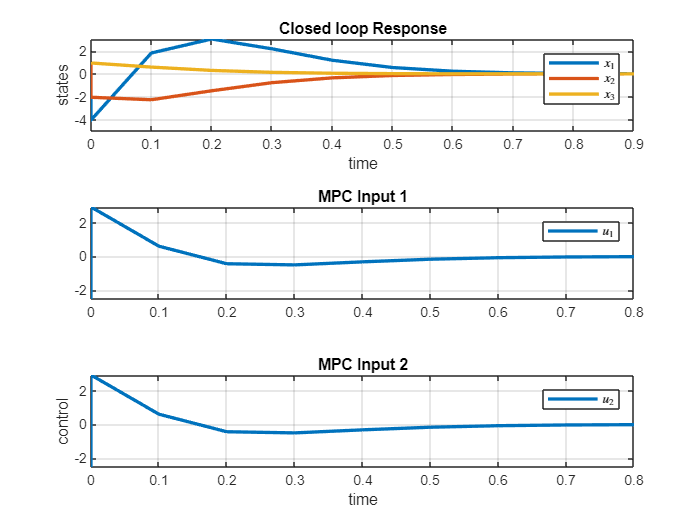

tiledlayout(3,1)

nexttile
plot(T_log,X_log, 'LineWidth',2); grid on;
title(sprintf('Closed loop Response'))
ylabel('states')
xlabel ('time');
LEG = legend('$x_1$', '$x_2$', '$x_3$');
set(LEG,'interpreter','latex')

nexttile
plot(T_log(1:end-1),U_log(1,:),'LineWidth',2); grid on;
title(sprintf('MPC Input 1'))
LEG = legend('$u_1$');
set(LEG,'interpreter','latex')

nexttile
plot(T_log(1:end-1),U_log(2,:),'LineWidth',2); grid on;
title(sprintf('MPC Input 2'))
ylabel('control')
xlabel ('time');
LEG = legend('$u_2$');
set(LEG,'interpreter','latex')

## Helper functions

getting a QP representation given the discrete time linear system and MPC paramters

%function [F, G, A_ineq, B_ineq] = get_QP(system,mpc,bounds)
    % Inputs
    % system.A (system dynamics)                    : n x n
    % system.B (control input)                      : n x p
    % system.C (system output)                      : n x m
    % mpc.P (termail cost)                          : n x 1
    % mpc.Q (state cost)                            : n(N-1) x n(N-1)
    % mpc.R (control cost)                          : p(N-1) x p(N-1)
    % mpc.N is prediction horizon                   : scalar
    % bounds.u_min is min the control bound         : scalar
    % bounds.u_max is max the control bound         : scalar
    % bounds.y_min is min the output bound          : scalar
    % bounds.y_max is min the output bound          : scalar
 
    % Outputs
    % G (augmented cost)                        : p(N) x p(N)
    % F (augmented cost)                        : p(N) x 1
    % augmented cost                            : 1/2 * X^T * G * X + X^T * F * x0
    % A_ineq (augmented ineq constraint A)      : (p+m)(N) x (p+m)(N)
    % B_ineq (augmented ineq constraint b)      : 2(p+m)(N) x 1
    % augmented ineq constraint                 : A_ineq * X <= b_ineq + b_ineqx0 * x0

    

solving the MPC as  QP problem

%function U = do_MPC(G,F,A_ineq,B_ineq,x)
    % Inputs
    % G (augmented cost)                        : p(N) x p(N)
    % F (augmented cost)                        : p(N) x 1
    % A_ineq (augmented ineq constraint A)      : (p+m)(N) x (p+m)(N)
    % B_ineq (augmented ineq constraint b)      : 2(p+m)(N) x 1
    % x (operating point)                       : n x 1

    % Outputs
    % U (MPC output)                            : p x 1